# Numerical Methods in Engineering

## Exercise 1: Linear Regression Revisited

**Given the following equations:**

$M\;\mathit{\mathbf{a}}=\mathit{\mathbf{y}}$**,  **$M \in \mathbb{R}^{m\times n}$** with **$m>n$

**To fit a **$n^{\textrm{th}}$**degree polynomial, **$p\left(x\right)=a_0 +a_1 x+a_{2\;} x^{2\;} +a_3 x^3 +\cdots +a_{n\;} x^n$** and find the coefficients **$\mathit{\mathbf{a}}=\left\lbrack a_{0\;} ,\;\;a_1 ,\;\;a_2 ,\cdots a_n \right\rbrack$**, the linear system shown below must be solved.**


$$\underset{\mathit{\mathbf{M}}}{\underbrace{\left\lbrack \begin{array}{ccccc}
1 & x_0  & x_0^2  & \cdots  & x_0^n \\
1 & x_1  & x_1^2  & \cdots  & x_1^n \\
1 & x_{2\;}  & x_{2\;}^2  & \cdots \; & x_{2\;}^n \\
\vdots \; & \vdots  & \vdots  & \ddots \; & \vdots \;\\
1 & x_{m-1}  & x_{m-1}^2  & \cdots  & x_{m-1}^n \\
1 & x_m  & x_m^2  & \cdots \; & x_m^n 
\end{array}\right\rbrack } }$$

$$\underset{\mathit{\mathbf{a}}}{\underbrace{\left\lbrack \begin{array}{c}
a_0 \\
a_1 \\
a_2 \\
\vdots \\
a_n 
\end{array}\right\rbrack } } =\underset{\mathit{\mathbf{y}}}{\underbrace{\left\lbrack \begin{array}{c}
y_0 \\
y_1 \\
y_2 \\
\vdots \\
y_{m-1} \\
y_m 
\end{array}\right\rbrack } }$$


**Given the data in Asst3_data_Q1a.mat, the data is loaded and plotted in the cell below. Note that the provided data files are present in the same directory as this script.**

load('Asst3_data_Q1a.mat'); % load the data 

x = x_given;
y = y_given; 

figure
plot(x,y,'rd',"LineWidth",2,"DisplayName",'data')
legend("Location","best") 
xlabel('x'); ylabel('y')
grid on; grid minor
title('Data Provided')

**a) The Vandermonde matrix, M, is constructed for the data provided. Suppose the provided data is modeled with a polynomial of degree 17. Using the cell below, a polynomial of degree 17 is fitted, i.e. **$p(x) = a_0 + a_1 x + a_2 x^2 + \dots + a_{17} x^{17}$**.  MATLAB's QR decomposition function is used to find the polynomial coefficients.**

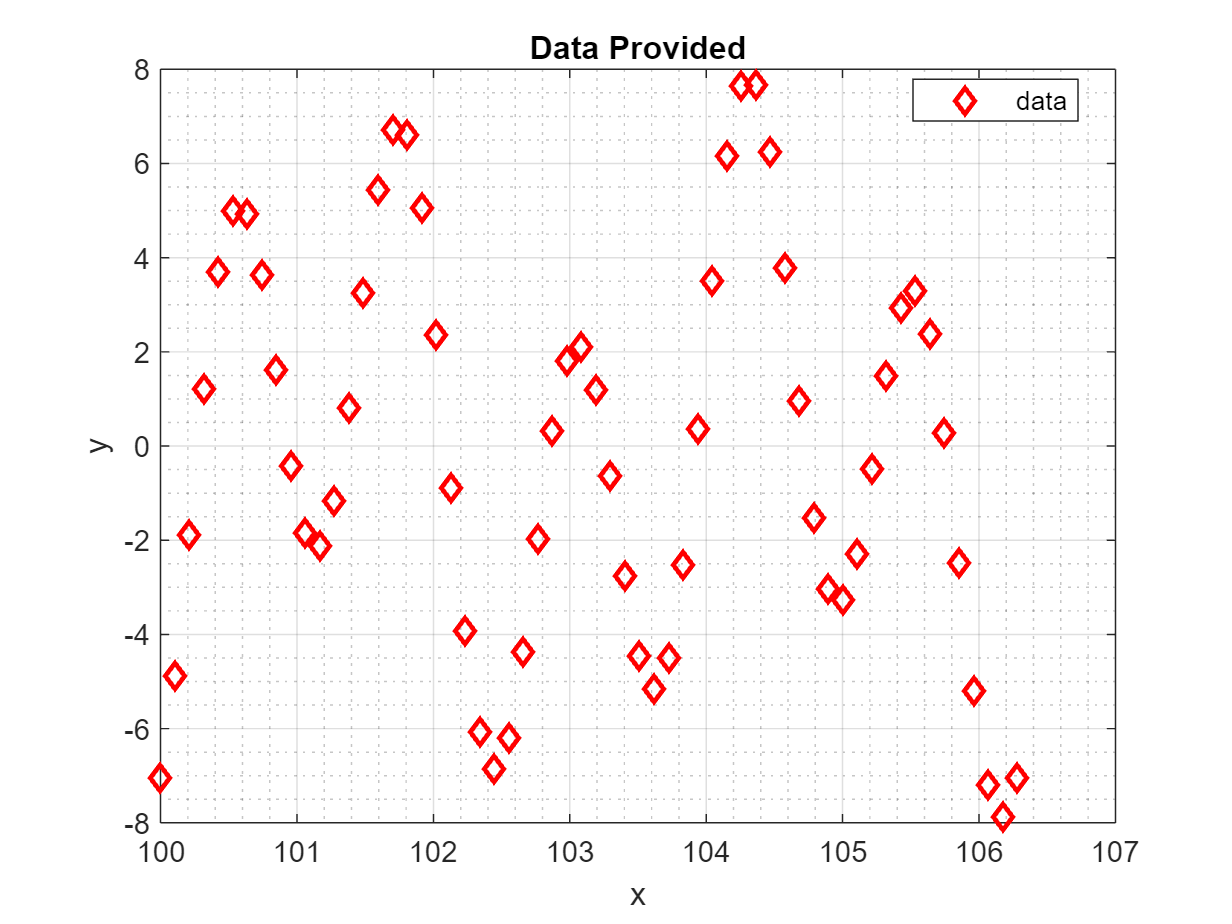

% Vandermonde Matrix 
polynomial_degree = 17;
vandermondeMatrix = VandermondeMatrix(x, polynomial_degree);
% disp(vandermondeMatrix);
% MATLAB QR Decomposition
[Q,R] = qr(vandermondeMatrix,"econ");

% The polynomial coefficients using Q & R matrices obtained below
y_sub = Q.'*y;
coefficients = R \ y_sub; 

**Using the obtained coefficients, **$a_i,  \;\;0\leq i \leq17$** , for the polynomial model, **$p(x) = a_0 + a_1 x + a_2 x^2 + \dots + a_{17} x^{17}$**, the model can be tested by evaluating **$p\left(x\right)$** at different values of **$x$**. Since the input data was linearly spaced between 100 to **$100+2\pi \;$**, 200 linearly spaced points are used to test the performance of the model.**

**In the cell below, the data used to build the model is used as a reference to test the performance of the obtained model by plotting it on the same graph. **

%----------------------------------------------------------------
x_test = linspace(100+0,100+2*pi,200);  % generate test data 
x_test = x_test.';
%----------------------------------------------------------------
powers = 0:polynomial_degree;
px = zeros(length(x_test),1);

for I = 1:length(powers)
   px = px + coefficients(I)*x_test.^powers(I); 
end


% Plots
figure
hold on
plot(x_given,y_given,'ro') % plot All Data
plot(x,y,'gd') % plot Used Data
plot(x_test,px,'b-.','Linewidth',2)
xlabel('x')
ylabel('y')
legend('Given Data','Data used','Obtained Model')
title({'Part 1a';'The Obtained Model Using 17^{th} Degree Polynomial'})
grid on

**Is the obtained model accurate? Suggestions are provided below on how to improve the performance of the model.**

*The obtained model from using 17th degree polynomial does a poor fitting to the overall curve displayed by the data. Upon closely inspecting the obtained model (blue curve), it can be seen that it contains a significant amount of oscillations when compared to the used data (green curve). This shows that the obtained model is significantly overfitting and suggests that a polynomial of 17 degrees may too complex for this curve. However, testing with other degree values it can be observed that the model never converges to the expected curve. This additionally gives the idea that perhaps the Vandermonde Matrix is too ill-conditioned that the resulting model will also be poor. *

*Observing the originally constructed Vandermonde matrix, it can be seen that the condition number is very high and even Matlab issues a warning that the matrix is "close to singular or badly scaled". One of the ways to improve the performance of the model would be to lower the condition number of the *matrix. *Observing the x_given values used to generate the matrix, it can be seen that they are all above 100 which can cause overflow when performing *$100^{17}$*. A solution would be lower the x_values such that they are within a smaller range. One way to ****normalize the data ****could be to subtract 100 from each of the x_given values.*

**b) If the polynomial model obtained in part a) is not accurate, appropriate changes are made to fit a polynomial model of order 17 shown in part a). The cell below to write your code. MATLAB's QR decomposition function is used to find the polynomial coefficients. The obtained model is plotted  along with the data used to build the model. **

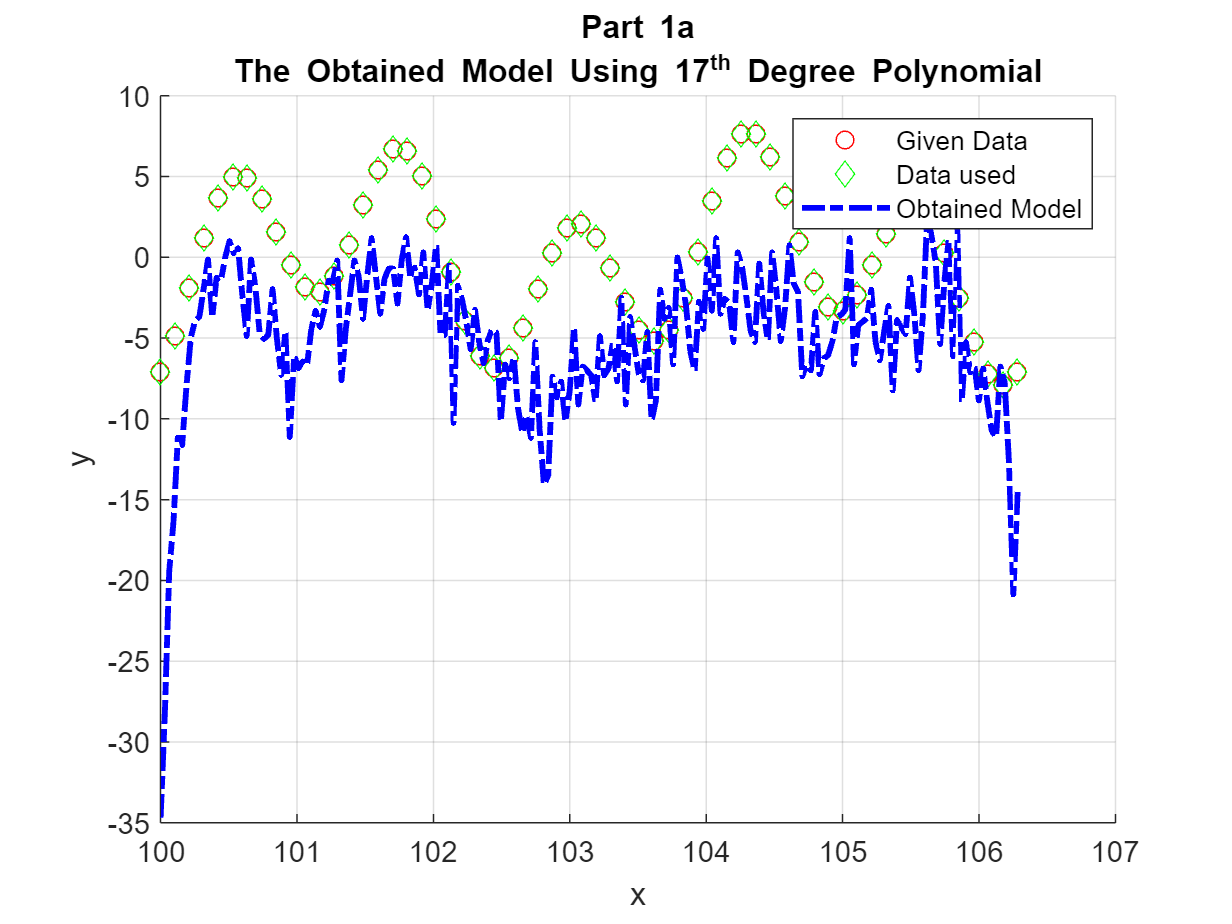

improved_x = x - 100;
polynomial_degree = 17;

improvedVandermondeMatrix = VandermondeMatrix(improved_x,polynomial_degree);
[Q,R] = qr(improvedVandermondeMatrix,"econ");
y_sub = Q.'*y;
improved_coefficients = R \ y_sub;

%----------------------------------------------------------------
x_test = linspace(0,2*pi,200) + 100;  % generate test data 

x_test = x_test.';
%----------------------------------------------------------------

px = zeros(length(x_test),1);
powers = 0:polynomial_degree;
for I = 1:length(powers)
    px = px + improved_coefficients(I)*(x_test-100).^powers(I);   
end

disp(improved_coefficients);
%plots
figure
hold on
plot(x,y,'ro')
plot(x_test,px,'b-.','Linewidth',2)
xlabel('x')
ylabel('y')
legend('Given Data','Obtained Model')
grid on
title({'Part 1b';'The Improved Model Using 17^{st} Degree Polynomial'})

**A brief summary on how the model was obtained.**

*As stated in the previous section, the correct model was obtained by improving the condition number of the Vandermonde matrix by modifying the x_given values that were used to construct it (normalization). Since the x_given values were all above 100, at higher powers (e.g. 17), the computation *$100^{17}$* would result in overflow which would result in a loss of information and contribute significantly to creating a poorly constructed model. The solution implemented above removes 100 from each of the x_given values thereby scaling the values in the vector to a reasonable size. The resulting data is used to constructed a Vandermonde matrix with a smaller condition number. As can be observed from the graph in part 1b, the resulting model constructed from the test data fits very well to the given data. *

**c) In this part, a new data set is loaded in the cell below and part b) is repeated: fitting a polynomial of degree 17, i.e. **$p(x) = a_0 + a_1 x + a_2 x^2 + \dots + a_{17} x^{17}$** to the provided data. A commont on the results in provided below. The obtained model along with the data used to build the model is plotted. **

*The data in Asst3_data_Q1c.mat is reasonably well ranged. However, after fitting the model, significant overfitting can be seen as the curve tries to pass through almost every point. *

load('Asst3_data_Q1c.mat');

   1.0e+04 *

   -0.0007
   -0.0062
    0.1295
   -0.7637
    2.4376
   -4.7871
    6.1653
   -5.4486
    3.4159
   -1.5546
    0.5209
   -0.1292
    0.0237
   -0.0032
    0.0003
   -0.0000
    0.0000
   -0.0000



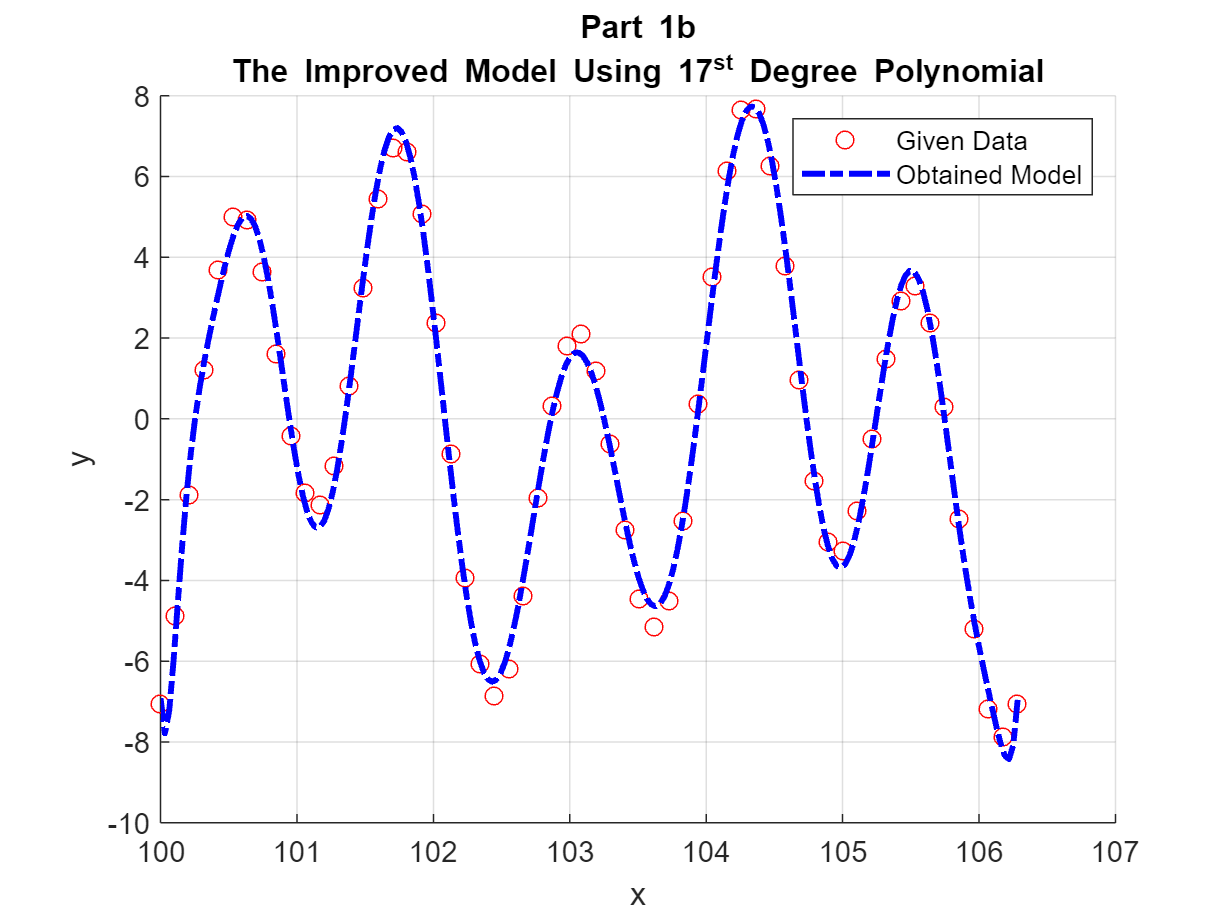


x2 = x_given; % input data
y2 = y_given; % output data
polynomial_degree = 17;

improvedVandermondeMatrix = VandermondeMatrix(x2,polynomial_degree);
[Q2,R2] = qr(improvedVandermondeMatrix,"econ");
y2_sub = Q2.'*y2;
improved_coefficients = R2 \ y2_sub;
%----------------------------------------------------------------

x2_test = linspace(0,2*pi,200);  % generate test data 
x2_test = x2_test.';
%----------------------------------------------------------------

px_c = zeros(length(x2_test),1);
powers = 0:polynomial_degree;
for I = 1:length(powers)
    px_c = px_c + improved_coefficients(I)*x2_test.^powers(I);   
end

%plots
figure
hold on
plot(x2,y2,'ro')
plot(x2_test,px_c,'b-.','Linewidth',2)
xlabel('x')
ylabel('y')
legend('Given Data','Obtained Model')
grid on
title({'Part 1c';'The Obtained Model Using 17^{st} Degree Polynomial UNREGULARIZED'})
ylim([min(y2)-1 max(y2)+3])

**d) For this part, a Tikhnov Regularisation-based algorithm is used to fit the data using the polynomial of degree 17. The algorithm is optimised for accuracy.  The cell below is used to compute the coefficients of **$17^{th}$** degree polynomial.  Trial and error was used to choose the value of regularisation constant, **$\lambda$**. The obtained model along with the data used to build the model is plotted below.**

polynomial_degree = 17;

improvedVandermondeMatrix = VandermondeMatrix(x2,polynomial_degree);
[row, col] = size(improvedVandermondeMatrix);

regularisation_constant = 0.003;

M = [improvedVandermondeMatrix ; regularisation_constant * eye(col)];
[Q3,R3] = qr(M,"econ");

y3_sub = Q3.'*[y2 ; zeros(col,1)];
improved_coefficients = R3 \ y3_sub;

**e) Using the cell below, the models obtained in part c) and d) are plotted along with the data used in building the models. A comment is provided on both models.**

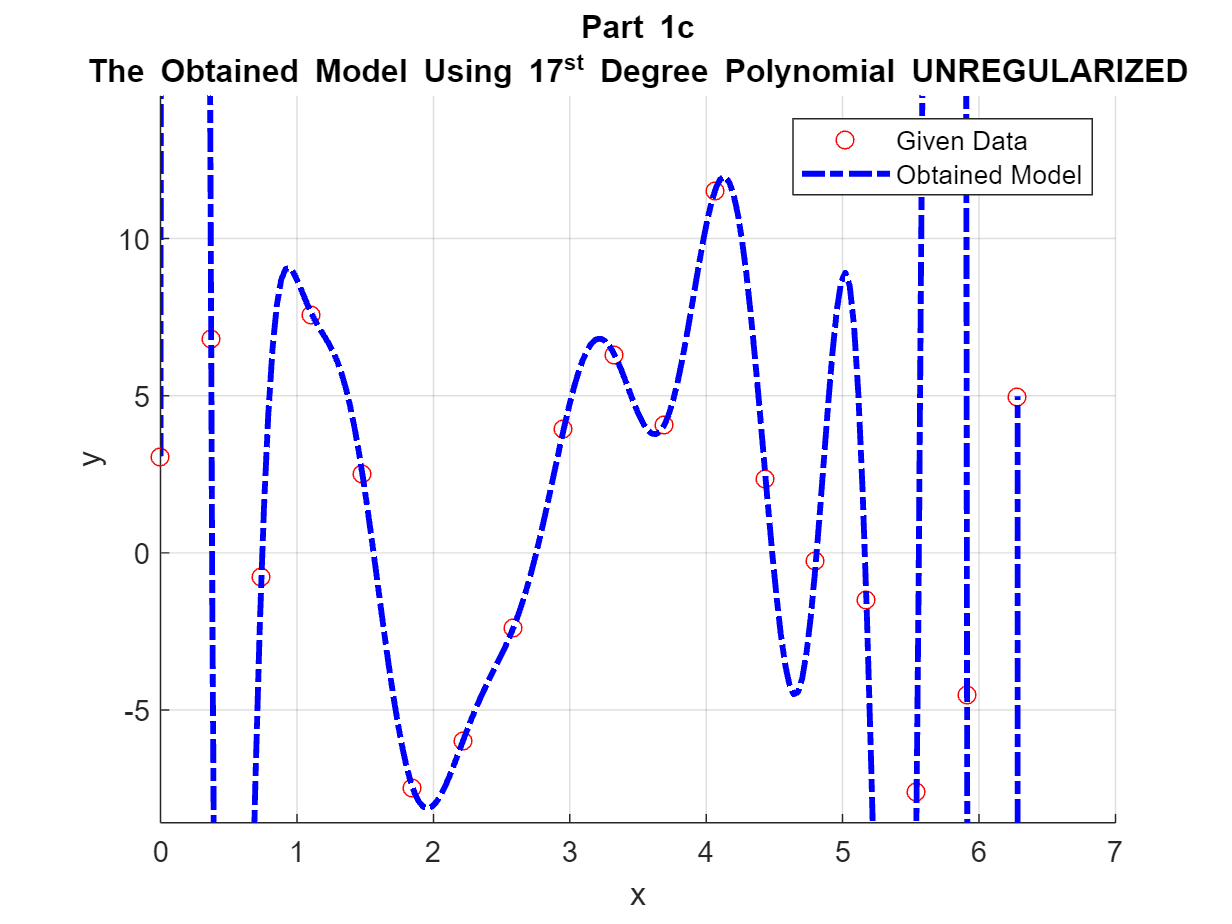

px_d = zeros(length(x2_test),1);
powers = 0:polynomial_degree;
for I = 1:length(powers)

    px_d = px_d + improved_coefficients(I)*x2_test.^powers(I);   
end

%plots
figure
hold on
plot(x2,y2,'ro')
plot(x2_test,px_d,'b-.','Linewidth',2)
plot(x2_test,px_c,'g-.','Linewidth',2)
xlabel('x')
ylabel('y')
legend('Given Data','Model Regularized', 'Model Not-Regularized')
legend('Location','southwest')
grid on
title({'Part 1e';'The Obtained Model Using 17^{st} Degree Polynomial'})
ylim([min(y2)-1 max(y2)+3])

**The comments for 1e) are provided below.**

*The unregularized model is significantly overfitting to the data (blue line) even though the data is scaled within a reasonable range. Regularization can be used to prevent overfitting in such case scenarios and choosing a regularization hyperparameter is also important. Observing the regularized model (green line), the model is much better fit to the data without overfitting or underfitting too much which means that the hyperparameter was well chosen. *

**f) The least squares regression is used to build the models based on the experimental data. As new experimental data is available, the obtained model must be updated. In this part, an algorithm will be designed to update the model coefficients when new data is available. Similar to the previous parts, a polynomial based model is used to fit to the provided data. **

**Suppose m-data points are available, the Vandermonde matrix syste can be written:**


$$\underset{\mathit{\mathbf{M}}}{\underbrace{\left\lbrack \begin{array}{ccccc}
1 & x_0  & x_0^2  & \cdots  & x_0^n \\
1 & x_1  & x_1^2  & \cdots  & x_1^n \\
\vdots \; & \vdots  & \vdots  & \ddots \; & \vdots \;\\
1 & x_m  & x_m^2  & \cdots \; & x_m^n 
\end{array}\right\rbrack } }$$

$$\underset{\mathit{\mathbf{a}}}{\underbrace{\left\lbrack \begin{array}{c}
a_0 \\
a_1 \\
\vdots \\
a_n 
\end{array}\right\rbrack } } =\underset{\mathit{\mathbf{y}}}{\underbrace{\left\lbrack \begin{array}{c}
y_0 \\
y_1 \\
\vdots \\
y_m 
\end{array}\right\rbrack } }$$


**Using the Normal equations, the least-square solution for the above system is given by:**


$${\mathit{\mathbf{M}}}^{T\;} \mathit{\mathbf{M}}\;\mathit{\mathbf{a}}={\mathit{\mathbf{M}}}^T \mathit{\mathbf{y}}$$


**In the following cell using the data provided in the file named, Asst3_data_Q1f.mat, a polynomial of order 2 is fitted using the Normal Equations. Matrix **${\mathit{\mathbf{M}}}^{T\;} \mathit{\mathbf{M}}$**is used explicitly to compute the least square solution for the above system of equations. **

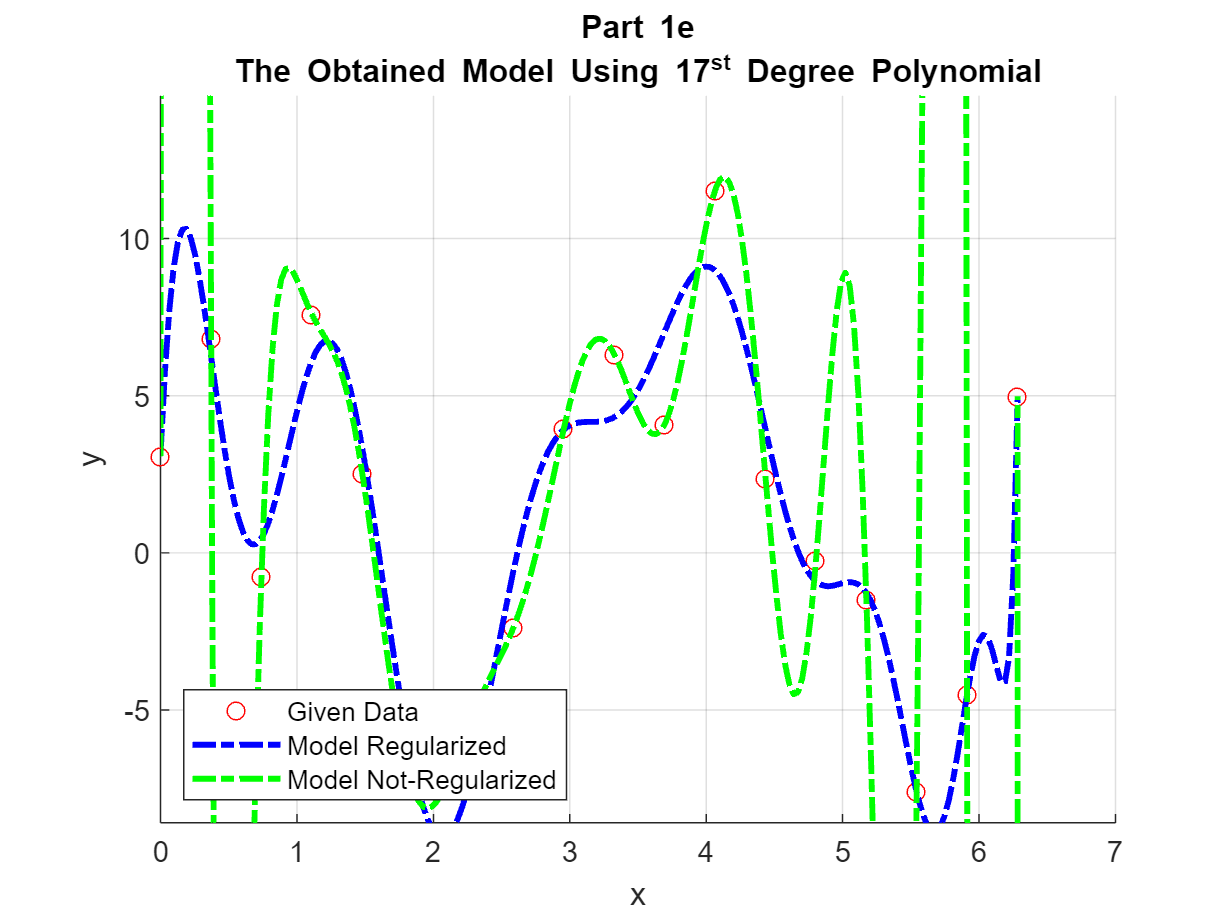

load('Asst3_data_Q1f.mat'); 
x = x_given;
y = y_given;

degree = 2;

M = VandermondeMatrix(x,degree);
U = chol(M.'*M);
L = U.';
B = M.'*y;
y_sub = forward_sub(L,B);
Ar = backward_sub(U,y_sub);

%----------------------------------------------------------------
x_test = linspace(-1,1,200);  % generate test data 
x_test = x_test.';
%----------------------------------------------------------------


px = zeros(length(x_test),1);
powers = 0:degree;
for I = 1:length(powers)
    px = px + Ar(I)*x_test.^powers(I);   
end
%plots
figure
hold on
plot(x,y,'ro')
plot(x_test,px,'b-.','Linewidth',2)
xlabel('x')
ylabel('y')
legend(' Given Data','Obtained Model')
grid on
title({'Part 1f';'The obtained model using 2^{st} degree Polynomial'})

**After running the experiment, new data is obtained: output **$y_{m+1}$** for input **$x_{m+1}$**. Using this, the new system can be updated:**


$$\left\lbrack \begin{array}{ccccc}
1 & x_0  & x_0^2  & \cdots  & x_0^n \\
1 & x_1  & x_1^2  & \cdots  & x_1^n \\
\vdots \; & \vdots  & \vdots  & \ddots \; & \vdots \;\\
1 & x_m  & x_m^2  & \cdots \; & x_m^n \\
1 & x_{m+1}  & x_{m+1}^2  & \cdots \; & x_{m+1}^n 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\hat{a} }_0 \\
{\hat{a} }_1 \\
\vdots \\
{\hat{a} }_n 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
y_0 \\
y_1 \\
\vdots \\
y_m \\
y_{m+1} 
\end{array}\right\rbrack$$


**Note that in the above system the coefficients will be updated. The above system can also we written as:**


$$\left\lbrack \begin{array}{c}
\mathit{\mathbf{M}}\\
{\mathit{\mathbf{v}}}^T 
\end{array}\right\rbrack \hat{\mathit{\mathbf{a}}} =\left\lbrack \begin{array}{c}
\mathit{\mathbf{y}}\\
y_{m+1} 
\end{array}\right\rbrack \;$$


**where, **${\mathit{\mathbf{v}}}^T$** is a row vector containing the polynomials evaluated at the input point **$x_{m+1}$**, i.e.,  **${\mathit{\mathbf{v}}}^T =\left\lbrack \begin{array}{ccccc}
1 & x_{m+1}  & x_{m+1}^2  & \cdots  & x_{m+1}^n 
\end{array}\right\rbrack$** and **$\hat{\mathit{\mathbf{a}}}$** is a column vector containing the updated coeffcients. **

x_mplus1 =  -3.1579e-01;
y_mplus1 =  1.5;

% Forming the vT vector
vT = VandermondeMatrix(x_mplus1, degree);
v = vT.';

**Knowing how to obtain the least squares solutions for the above equation, the following normal equations can be constructed:**


$${\left\lbrack \begin{array}{c}
\mathit{\mathbf{M}}\\
{\mathit{\mathbf{v}}}^T 
\end{array}\right\rbrack }^T \left\lbrack \begin{array}{c}
\mathit{\mathbf{M}}\\
{\mathit{\mathbf{v}}}^T 
\end{array}\right\rbrack \hat{\mathit{\mathbf{a}}} ={\left\lbrack \begin{array}{c}
\mathit{\mathbf{M}}\\
{\mathit{\mathbf{v}}}^T 
\end{array}\right\rbrack }^{T\;} \left\lbrack \begin{array}{c}
\mathit{\mathbf{y}}\\
y_{m+1} 
\end{array}\right\rbrack$$


**Upon multiplying the above matrices the following is obtained:**


$$\left\lbrack \begin{array}{c}
{\mathit{\mathbf{M}}}^{T\;} \mathit{\mathbf{M}}+\mathit{\mathbf{v}}\;{\mathit{\mathbf{v}}}^T 
\end{array}\right\rbrack \;\hat{\mathit{\mathbf{a}}} =\left({\mathit{\mathbf{M}}}^{T\;} \mathit{\mathbf{y}}+y_{m+1\;} \mathit{\mathbf{v}}\right)$$
 

**Using the Sherman-Morrison formula, the inverse of the matrix **$\left(\mathit{\mathbf{B}}+\mathit{\mathbf{v}}\;{\mathit{\mathbf{v}}}^T \right)$** can be written as:**


$${\left(\mathit{\mathbf{B}}+\mathit{\mathbf{v}}\;{\mathit{\mathbf{v}}}^{\mathit{\mathbf{T}}} \right)}^{-1\;} ={\mathit{\mathbf{B}}}^{-1\;} -\frac{{\mathit{\mathbf{B}}}^{-1\;} \mathit{\mathbf{v}}\;{\mathit{\mathbf{v}}}^{\mathit{\mathbf{T}}} \;{\mathit{\mathbf{B}}}^{-1} }{1+{\mathit{\mathbf{v}}}^{\mathit{\mathbf{T}}\;} {\mathit{\mathbf{B}}}^{-1} \mathit{\mathbf{v}}}$$


**Using the coefficeints, **$\mathit{\mathbf{a}}$**, which are already computed by solving **${\mathit{\mathbf{M}}}^{T\;} \mathit{\mathbf{M}}\;\mathit{\mathbf{a}}={\mathit{\mathbf{M}}}^T \mathit{\mathbf{y}}$**, the Sherman-Morrison formula can be used to compute the updated coefficients in**$\;\hat{\mathit{\mathbf{a}}}$** without explicitly decomposing **$\left({\mathit{\mathbf{M}}}^T \mathit{\mathbf{M}}+\mathit{\mathbf{v}}\;{\mathit{\mathbf{v}}}^T \right)$**or computing the inverse of **${\mathit{\mathbf{M}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{M}}$**. The code for this approach is written below. **


$$\text{Substituting } \hat{a} = a+{\Delta} \text{ into }\left[M^TM+vv^t\right]\hat{a}=\left(M^Ty+y_{m+1}v\right) \\
\text{to obtain } M^TMa+vv^ta+\left[M^TM+vv^t\right]{\Delta}=M^Ty+y_{m+1}v \\
\text{The equation can further be reduced to } vv^ta+\left[M^TM+vv^t\right]{\Delta}=y_{m+1}v \text{ using } M^TMa=M^Ty \\
\text{After rearranging, } {\Delta}=\left[M^TM+vv^t\right]^{-1}\left(y_{m+1}v-vv^ta\right) \\
\text{Using the Sherman-Morrison formula } B = M^TM \text{ the new delta is } {\Delta}=\left(B^{-1}-\frac{B^{-1}vv^tB^{-1}}{1+v^TB^{-1}v}\right)\left(y_{m+1}v-vv^ta\right) \\
\text{Plugging everything back in to obtain the new $a$ hat: }
\hat{a}=a+\left(B^{-1}-\frac{B^{-1}vv^tB^{-1}}{1+v^TB^{-1}v}\right)\left(y_{m+1}v-vv^ta\right)
$$


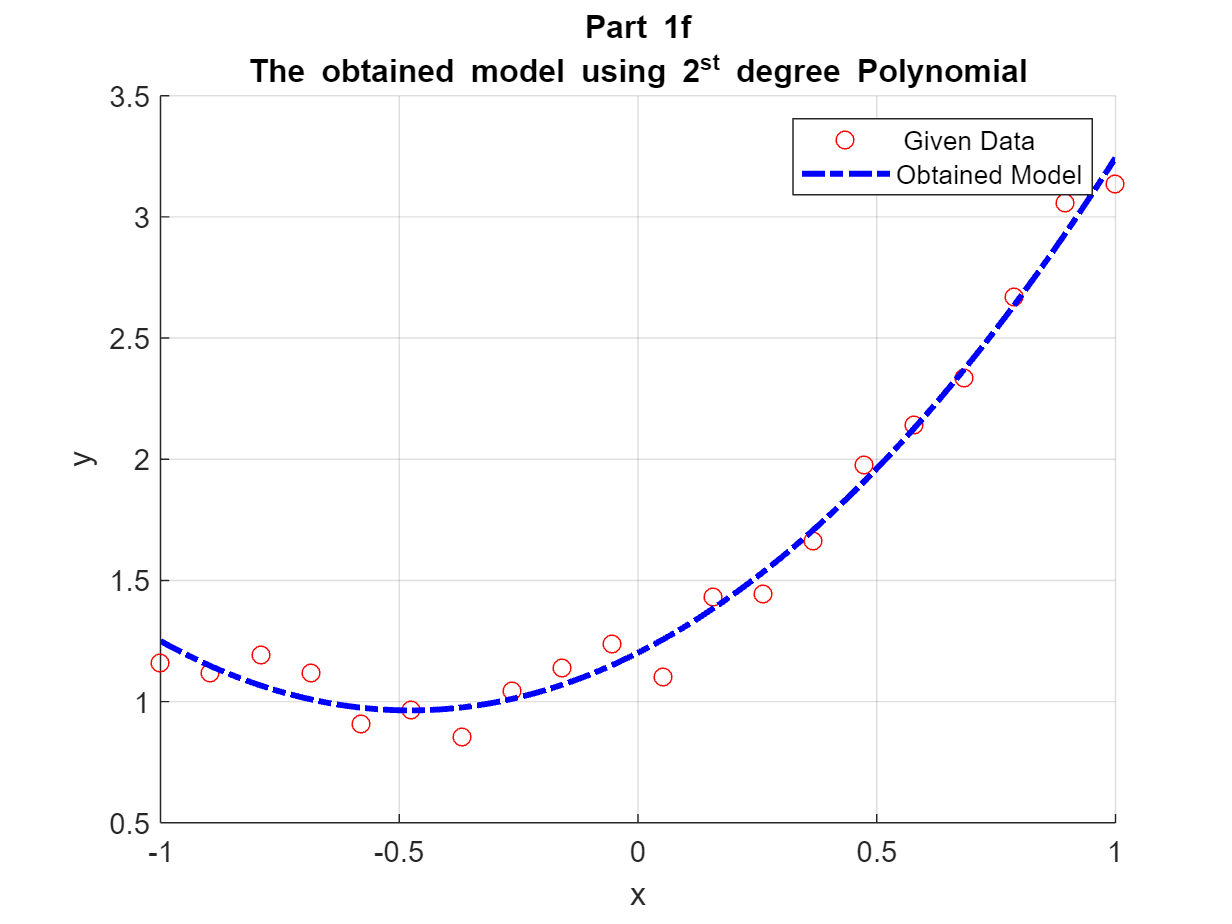

% Partial recalculation using the above derivations derived from Sherman-Morrison (efficient)
U_inv = zeros(size(U));

U_inv(:,1) = backward_sub(U,[1;0;0]).';
U_inv(:,2) = backward_sub(U,[0;1;0]).';
U_inv(:,3) = backward_sub(U,[0;0;1]).';

B_inv = U_inv*(U_inv).';
Sherman = B_inv - (B_inv*v*vT*B_inv)/(1+vT*B_inv*v);
A_hat = Ar+Sherman*(y_mplus1*v-v*vT*Ar);

%----------------------------------------------------------------
x_test = linspace(-1,1,200);  % generate test data 
x_test = x_test.';
%----------------------------------------------------------------

px = zeros(length(x_test),1);
powers = 0:degree;
for I = 1:length(powers)

    px = px + A_hat(I)*x_test.^powers(I);   
end

x_new = [x',x_mplus1]';
y_new = [y',y_mplus1]';

%plots
figure
hold on
plot(x_new,y_new,'ro')
plot(x_test,px,'b-.','Linewidth',2)
xlabel('x')
ylabel('y')
legend(' Given Data','Obtained Model')
grid on
title({'Part 1f';'Sherman-Morrison recalculated model with an additional data point using 2^{st} degree Polynomial'})
% The expected results by recalculating and refitting the model
% (inneficient). This is just to see that the model is still fit correctly.
% 
M = VandermondeMatrix(x_new,degree);
U = chol(M.'*M);
L = U.';
B = M.'*y_new;
y_sub = forward_sub(L,B);
A = backward_sub(U,y_sub);

%----------------------------------------------------------------
x_test = linspace(-1,1,200);  % generate test data 
x_test = x_test.';
%----------------------------------------------------------------

px = zeros(length(x_test),1);
powers = 0:degree;
for I = 1:length(powers)
    px = px + A(I)*x_test.^powers(I);   
end

%plots
figure
hold on
plot(x_new,y_new,'ro')
plot(x_test,px,'b-.','Linewidth',2)
xlabel('x')
ylabel('y')
legend(' Given Data','Obtained Model')
grid on
title({'Part 1f';'Fully recalculated model with an additional data point using 2^{st} degree Polynomial'})

**Sources used to complete this section:**

- [https://www.simplilearn.com/tutorials/machine-learning-tutorial/regularization-in-machine-learning](https://www.simplilearn.com/tutorials/machine-learning-tutorial/regularization-in-machine-learning)

- https://en.wikipedia.org/wiki/Sherman%E2%80%93Morrison_formula

## Exercise 2: **Nonlinear Equations for Univariate Case**

a) **The Bisection method is used for finding the roots of a continuous function, **$f\left(x\right)$**, given endpoints **$a,b$** with **$f\left(a\right)*f\left(b\right)<0$**. The interval **$\left\lbrack a\;\;b\right\rbrack$**contains a root, **$x_r$**, because **$f\left(a\right)$** and **$f\left(b\right)$** have opposite signs.**

**Bisection method bisects the given interval at the midpoint **$c=\frac{a+b}{2}$** and then chooses a new interval such that end of points of interval have opposite signs. For example, if **$f\left(a\right)*f\left(c\right)<0$**, then the new interval is set to **$\left\lbrack a,\;\;c\right\rbrack$**, else if **$f\left(c\right)*f\left(b\right)<0$**, then the interval is set to **$\left\lbrack c,\;\;b\right\rbrack$**.**

**The above procedure is repeated until the following two conditions are simultaneously met: **

- **The function value at the interval is sufficiently small, i.e., **${\left\|f\left(c\right)\right\|}_2 <\epsilon_{\textrm{tolerance}}$

- **The new interval is sufficiently small, i.e., **${\left\|a-b\right\|}_2 <\epsilon_{\textrm{tolerance}}$

**The Bisection Method is implemented in the appendix and tested in the cell below. It is used to find the root of **$f\left(x\right)=x^4 -{2\;x}^2 -4$** in the interval **$\left\lbrack -3,\;\;\;0\right\rbrack \;$**using a tolerance of **$\epsilon_{\textrm{tolerance}} ={10}^{-5}$**. The number of iterations that the bisection method took to converge are additionally shown below.**

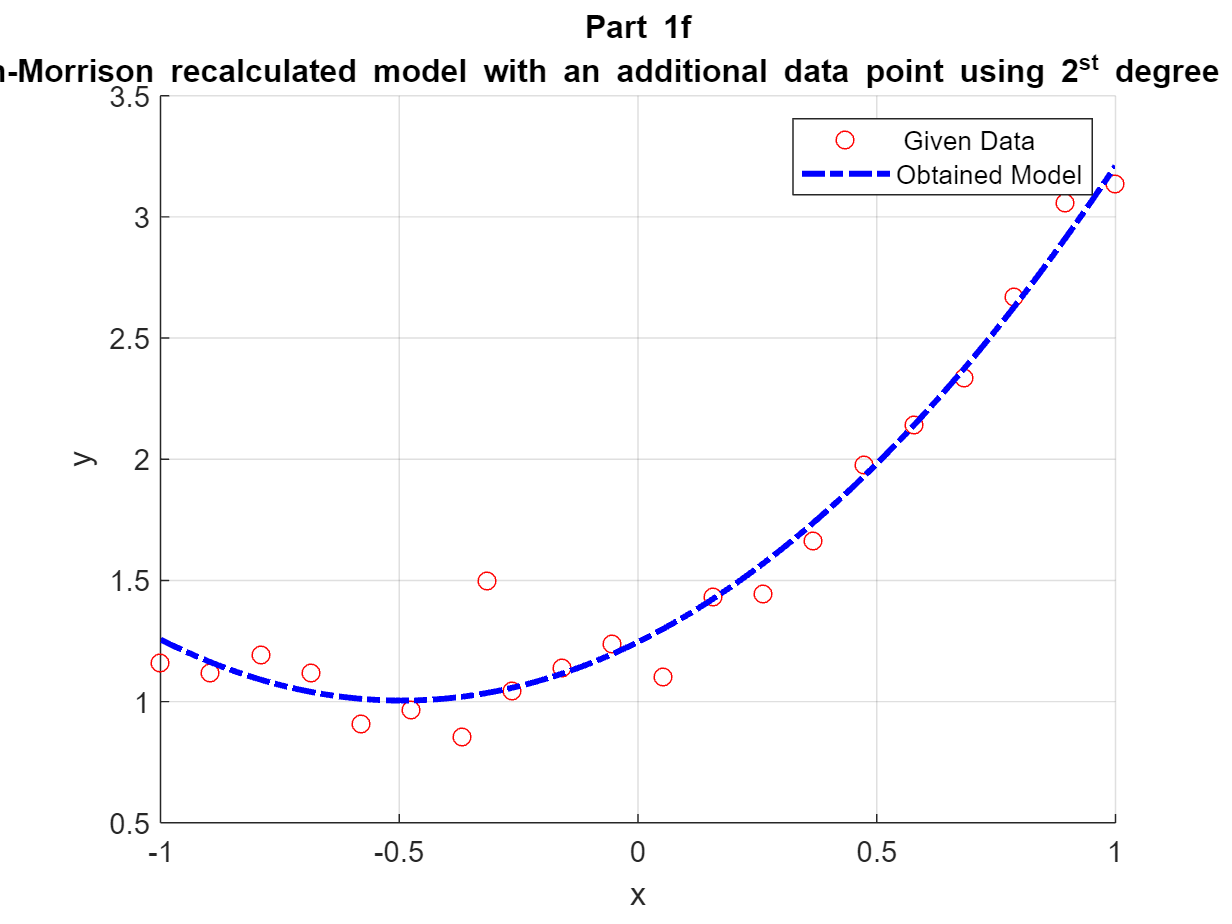

f = @(x) x^4 - 2*x^2 - 4;
a = -3;
b = 0;
tolerance = 1e-5;

[c, counter] = bisectionMethod(f, a, b, tolerance);


% Display the result
fprintf('Root found at x = %.6f after %d iterations\n', c, counter);

**b)  Newton-Raphson Method**

**The Bisection method requires the given function,**$f\left(x\right)$**, to be continuous. On the other hand, the Newton-Raphson method requires **$f\left(x\right)$** to be continuous and differentiable. While the Newton-Raphson method converges faster than the bisection method, it does not guarantee convergence. The Newton-Raphson method works by linearising the **$f\left(x\right)$**, at the given initial guess, **$x^{\left(0\right)}$**as shown below. **

$f\left(x\right)=f\left(x^{\left(0\right)} \right)+{f\left(x^{\left(0\right)} \right)}^{\prime } \left(x-x^{\left(0\right)} \right)$**`**

**To get an approximation to the root, the **$f(x)$** in the above expression is set to 0 obtaining the equivalence below:**


$$x^{\left(1\right)} =x^{\left(0\right)} -\frac{f\left(x^{\left(0\right)} \right)}{{f\left(x^{\left(0\right)} \right)}^{\prime } }$$


**The function,**$\;f\left(x\right)$**, is again linearised using approximation**$x^{\left(1\right)}$**as the initial guess, to obtain new approximation of the root. After **$k$** iterations the new approximation for the root becomes:**

  
$$x^{\left(k+1\right)} =x^{\left(k\right)} -\frac{f\left(x^{\left(k\right)} \right)}{{f\left(x^{\left(k\right)} \right)}^{\prime } }$$


**The above procedure is repeated untill the following two convergence condtions are simultaneously met:  **

- **The function value at new guess point is sufficiently small, i.e., **${\left\|f\left(x^{\left(k+1\right)} \right)\right\|}_2 <\epsilon_{\textrm{tolerance}}$

- **The difference between the two consecutive solutions is sufficiently small, i.e., **${\left\|\Delta x^{\left(k+1\right)} \right\|}_2 <\epsilon_{\textrm{tolerance}}$

**where **$\Delta x^{\left(k+1\right)} =$$x^{\left(k+1\right)} -x^{\left(k\right)}$**.**

**The cell below is used to test the Newton-Raphson Method implemented in the appendix. It is used to find the root of **$f\left(x\right)=x^4 -{2\;x}^2 -4$** with an intial guess of **$x^{\left(0\right)} =-3$** using a tolerance of **$\epsilon_{\textrm{tolerance}} ={10}^{-5}$**.  If the convergence is not reached in 100 iterations, the algorithm is terminated by displaying an error message indicating that Newton-Raphson failed to converge. **

**The 2-Norm of difference is plotted between consecutive solutions **${\left\|x^{\left(k+1\right)} -x^{\left(k\right)} \right\|}_2$**  for each iteration. **

f = @(x) x^4 - 2*x^2 - 4;
fderivative = @(x) 4*x^3 - 4*x;
x0 = -3; % initial guess
tolerance = 1e-5; 
max_iterations = 100;

% Run the Newton-Raphson method
[x, deltaX] = newtonraphson(f, fderivative, x0, tolerance, max_iterations)
% Plot the 2-Norm of the difference between consecutive solutions
figure;
plot(deltaX);
xlabel('Iteration Number');
ylabel('2-Norm of Difference Between Consecutive Solutions');
title('Convergence of the Newton-Raphson Method');
xlim([0, length(deltaX)]);

**Sources used to complete this section:**

- [https://byjus.com/maths/bisection-method/#:~:text=The%20bisection%20method%20is%20an,found%2C%20which%20is%20extremely%20small](https://byjus.com/maths/bisection-method/#:~:text=The%20bisection%20method%20is%20an,found%2C%20which%20is%20extremely%20small)

- [https://en.wikipedia.org/wiki/Newton%27s_method](https://en.wikipedia.org/wiki/Newton%27s_method)

- https://www.youtube.com/watch?v=nW6tkLhBiIQ&ab_channel=JaisohnKimVT

## Exercise 3: **Nonlinear Equations for N-variables**

 **Newton-Raphson Method can additionally be used to solve the system of nonlinear equations of N-variables, **$\left\lbrack x_1 ,\;x_2 ,\;\cdots ,\;x_n \right\rbrack$**:**


$$f_1 \left(x_1 ,x_2 ,\cdots ,x_N \right)=0$$



$$f_2 \left(x_1 ,x_2 ,\cdots ,x_N \right)=0$$
 


$$\vdots$$



$$f_N \left(x_1 ,x_2 ,\cdots ,x_N \right)=0$$


**The above equations can be written as a vector valued function, where **$\mathit{\mathbf{X}}=\left\lbrack x_1 ,x_2 ,\cdots ,x_N \right\rbrack$** is the vector containing all the variables:**


$$\mathit{\mathbf{f}}\left(\mathit{\mathbf{X}}\right)=\left\lbrack \begin{array}{c}
f_1 \left(x_1 ,x_2 ,\cdots ,x_N \right)\\
f_2 \left(x_1 ,x_2 ,\cdots ,x_N \right)\\
\vdots \\
f_N \left(x_1 ,x_2 ,\cdots ,x_N \right)
\end{array}\right\rbrack$$


**Following the idea of unidimensional Newton-Rapshson, start with an initial guess **${\mathit{\mathbf{X}}}^{\left(0\right)}$** and use this to linearise the function **$\mathit{\mathbf{f}}\left(\mathit{\mathbf{X}}\right)$** around**${\;\mathit{\mathbf{X}}}^{\left(0\right)}$** ;**


$$\mathit{\mathbf{f}}\left(\mathit{\mathbf{X}}\right)=\;$$

$$f\left({\mathit{\mathbf{X}}}^{\left(0\right)} \right)+\left(\frac{\partial }{\partial \mathit{\mathbf{X}}}\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(0\right)} \right)\right)\left(\mathit{\mathbf{X}}-{\mathit{\mathbf{X}}}^{\left(0\right)} \right)$$


**Setting **$f(X)$** to zero, it is possible to find the approximation of the solution vector. After **$k$** iterations, the approximation for the solution vector can be written as**

${\mathit{\mathbf{X}}}^{\left(k+1\right)} =$${\mathit{\mathbf{X}}}^{\left(k\right)} -{\left(\frac{\partial }{\partial \mathit{\mathbf{X}}}\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)\right)}^{-1} \mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)$**,**

**where **$\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)$** is the vector valued function evaluated at **${\mathit{\mathbf{X}}}^{\left(k\right)}$** and **$\left(\frac{\partial }{\partial \mathit{\mathbf{X}}}\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)\right)$** is the jacobian evaluated at **${\mathit{\mathbf{X}}}^{\left(k\right)}$**. The structure of the Jacobian is given by:**


$$\frac{\partial }{\partial \mathit{\mathbf{X}}}\mathit{\mathbf{f}}\left(\mathit{\mathbf{X}}\right)=\left\lbrack \begin{array}{cccc}
\frac{\partial f_1 }{\partial x_1 } & \frac{\partial f_1 }{\partial x_2 } & \cdots  & \frac{\partial f_1 }{\partial x_n }\\
\frac{\partial f_2 }{\partial x_1 } & \frac{\partial f_2 }{\partial x_2 } & \cdots  & \frac{\partial f_2 }{\partial x_n }\\
\vdots  & \vdots  & \ddots  & \vdots \\
\frac{\partial f_n }{\partial x_1 } & \frac{\partial f_n }{\partial x_2 } & \cdots  & \frac{\partial f_n }{\partial x_n }
\end{array}\right\rbrack$$


**The above procedure is repeated untill the following two convergence condtions are simultaneously met:**

- **The function value at new guess point is sufficiently small, i.e., **${\left\|\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k+1\right)} \right)\right\|}_2 <\epsilon_{\textrm{tolerance}}$

- **The difference between the two consecutive solutions is sufficiently small, i.e., **${\left\|{\mathit{\mathbf{X}}}^{\left(k+1\right)} -{\mathit{\mathbf{X}}}^{\left(k\right)} \right\|}_2 <\epsilon_{\textrm{tolerance}}$

**A solution to the following system three nonlinear equations is computed using the Newton-Raphson method.**


$${9x}_{1\;}^{2\;} +x_{2\;}^{2\;} +x_3^2 \;=3$$



$$x_{1\;}^{2\;} +\;{2x}_2^2 -x_{3\;} =2$$



$$x_{1\;} +x_{2\;} +12x_3 =5$$


**Note that the above equations can be expressed as **

$\mathit{\mathbf{f}}\left(\mathit{\mathbf{X}}\right)=\left\lbrack \begin{array}{c}
{9x}_{1\;}^{2\;} +x_{2\;}^{2\;} +x_3^2 -3\\
x_{1\;}^{2\;} +\;{2x}_2^2 -x_{3\;} -2\\
x_{1\;} +x_{2\;} +12x_3 -5
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack$**,        where **$\mathit{\mathbf{X}}={\left\lbrack \begin{array}{ccc}
x_1  & x_2  & x_3 
\end{array}\right\rbrack }^T$

**a) A function named *****evaluateEquations(x) *****is written in the appendix and is used to evaluate the above equation at a given input vector. The provided **$\mathit{\mathbf{X}}$** is used to check the implementation.**

X = [2;3;4];
f  = evaluateEquations(X)

**b) A function named *****evaluateJacobian()***** evaluates the Jacobian of the above equations. The provided **$\mathit{\mathbf{X}}$** is used to check the implementation.**

X = [2;3;4];
J  = evaluateJacobian(X)

**Newton-Raphson **

**c) The function named *****NewtonRaphson()***** in the appendix** **is used to implement the Newton-Raphson method. It uses methods implemented in part a) and b).**

**After trying the initial guess of **$X^{\left(0\right)} ={\left\lbrack \begin{array}{ccc}
0 & 0 & 0
\end{array}\right\rbrack }^T$**, it was discovered the computations become unstable. An initial guess of **$X^{\left(0\right)} ={\left\lbrack \begin{array}{ccc}
2 & 3 & 4
\end{array}\right\rbrack }^T$** is used instead. The 2-Norm of difference between consecutive solutions **${\left\|{\mathit{\mathbf{X}}}^{\left(k+1\right)} -{\mathit{\mathbf{X}}}^{\left(k\right)} \right\|}_2$** for each iteration is plotted below.**

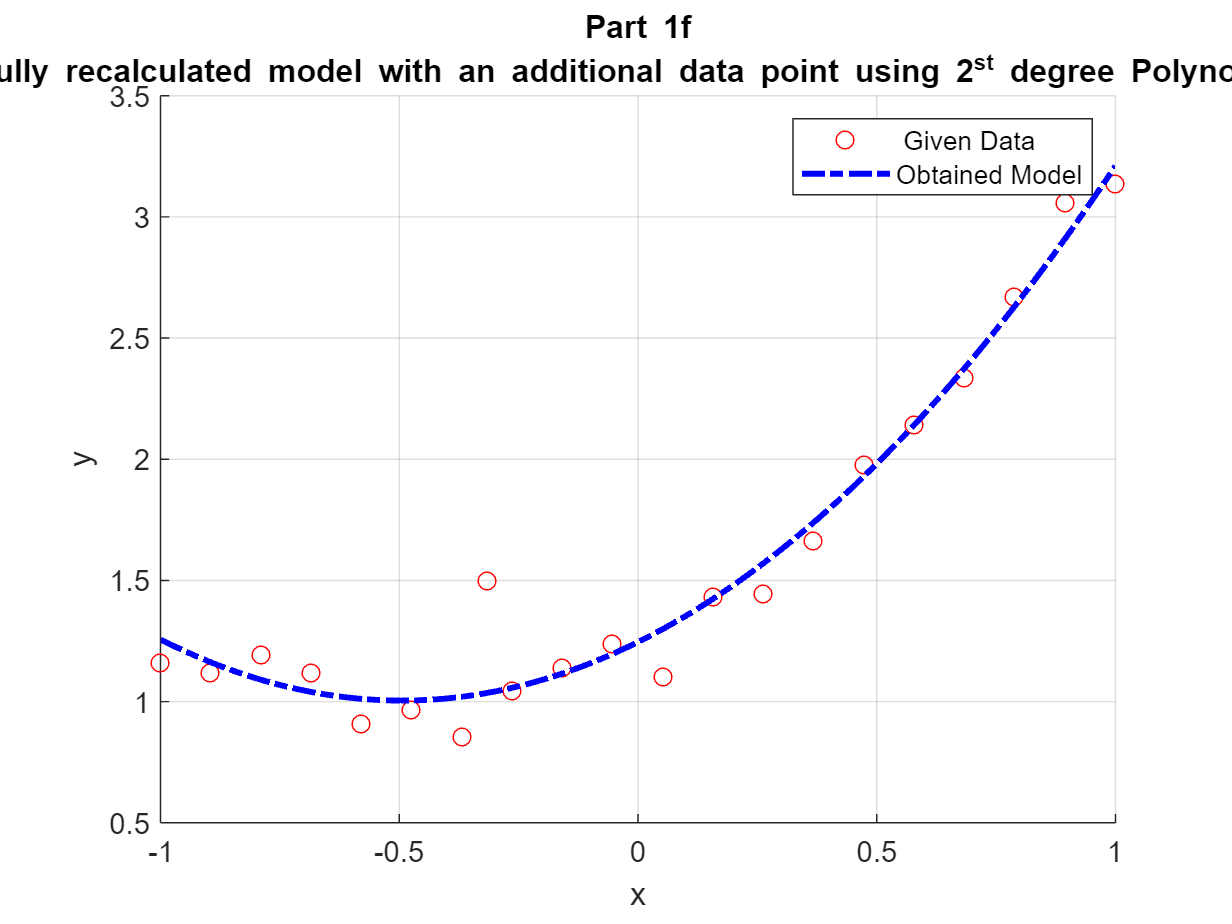

% Xguess = [0;0;0]; % causes instability so not used
Xguess = [2;3;4];
func = @evaluateEquations;
Jacobian = @evaluateJacobian;
[X, deltaX] = NewtonRaphson(func, Jacobian, Xguess, 1e-5)

figure()
plot(deltaX,'r-*')
xlabel('Iterations')
ylabel('$ || \Delta \textbf{X} || $ ', 'Interpreter', 'latex')
grid on
title('$ || \Delta \textbf{X} || $  vs Iterations curve for Newton-Raphson', 'Interpreter', 'latex')

**Newton-Raphson with Broyden's Method to Approximate Jacobian**

**d) Suppose it is not possible to get the Jacobian of the nonlinear equations directly. Instead, Broyden's method can be used to approximate the Jacobian.**

**At the **$(k+1)^{th}$** iteration of Newton Raphson, the soltuion vector **$\mathit{\mathbf{X}}$** is given by the equation below:**


$${\mathit{\mathbf{X}}}^{\left(k+1\right)} =$$

$${\mathit{\mathbf{X}}}^{\left(k\right)} -{\left(\frac{\partial }{\partial \mathit{\mathbf{X}}}\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)\right)}^{-1} \mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)$$


**Let, **$J_{k\;} =\;\left(\frac{\partial }{\partial \mathit{\mathbf{X}}}\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)\right)$**. Using the Broyden's update, **$J_{k\;}$** can be computed: **


$$J_{k\;} =J_{k-1} +\;\frac{\;\left(\;\;\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)-\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k-1\right)} \right)\;\;\right)\;-\;\;J_{k-1} \;\;\left({\;\mathit{\mathbf{X}}}^{\left(k\right)} -{\mathit{\mathbf{X}}}^{\left(k-1\right)\;} \right)\;}{{\left\|\;\;\left({\;\;\mathit{\mathbf{X}}}^{\left(k\right)} -{\mathit{\mathbf{X}}}^{\left(k-1\right)} \;\;\right)\;\;\right\|}_2^{2\;} }{\left({\;\;\mathit{\mathbf{X}}}^{\left(k\right)} -{\mathit{\mathbf{X}}}^{\left(k-1\right)} \;\right)}^T$$


**In the appendix, a function named***** NR_Broyden_Jacobian() *****is written to evaluate the Jacobian of the above equations. **

**The initial guess,**$X^{\left(0\right)}$,** that was used in part c) is used as the intial guess for the Jacobian **$J_0  =I_{n\times n}$**, where **$I_{n\times n}$** is the identity matrix and **$n$** is the number of equations. **

Xguess = [2;3;4];
func = @evaluateEquations;
[Xout, deltaXBroyden] = NR_Broyden_Jacobian(func, Xguess,1e-5)
figure()
plot(deltaXBroyden,'b-*')
xlabel('Iterations')
ylabel(' $ || \Delta \textbf{X} || $ ', 'Interpreter', 'latex')
grid on
title(' $ || \Delta \textbf{X} || $  curve  for Newton-Raphson using approximation of $J$', 'Interpreter', 'latex')

Root found at x = -1.798903 after 18 iterations


**Newton-Raphson with Broyden's Method to approximate the Inverse of Jacobian**

**e)  In part d) , Broyden's method for approximating the Jacobian was implemented. In this part, Broyden's update is used for computing the inverse of the Jacobian. The inverse of Jacobian can be computed as: **


$$J_{k\;}^{-1} =J_{k-1}^{-1} +\;\frac{\;\left(\;{\;\mathit{\mathbf{X}}}^{\left(k\right)} -{\mathit{\mathbf{X}}}^{\left(k-1\right)\;} \;\right)-\;J_{k-1}^{-1\;} \;\;\left(\;\;\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)-\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k-1\right)} \right)\;\;\right)\;}{{\left(\;{\;\mathit{\mathbf{X}}}^{\left(k\right)} -{\mathit{\mathbf{X}}}^{\left(k-1\right)\;} \;\right)}^{T\;} J_{k-1}^{-1} \;\;\left(\;\;\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k\right)} \right)-\mathit{\mathbf{f}}\left({\mathit{\mathbf{X}}}^{\left(k-1\right)} \right)\;\;\right)}\left({\left(\;{\;\mathit{\mathbf{X}}}^{\left(k\right)} -{\mathit{\mathbf{X}}}^{\left(k-1\right)\;} \;\right)}^{T\;} \;J_{k-1}^{-1} \right)$$


**A function named***** NR_Broyden_InvJacobian() *****is implemented in the appendix, it evaluates the Jacobian of the above equations. **

**The initial guess,**$X^{\left(0\right)}$,** that was used in part c) is used as the intial guess for the Jacobian **$J_0  =I_{n\times n}$**, where **$I_{n\times n}$** is the identity matrix and **$n$** is the number of equations. **

Xguess = [2;3;4];
func = @evaluateEquations;
[Xout,deltaXBroyden]  = NR_Broyden_InvJacobian(func, Xguess,1e-5)
figure()
plot(deltaXBroyden,'g-*')
xlabel('Iterations')
ylabel(' $ || \Delta \textbf{X} || $ ', 'Interpreter', 'latex')
grid on

x = -1.7989

deltaX =     0.6146
    0.3798
    0.1705
    0.0348
    0.0013
    0.0000


title(' $ || \Delta \textbf{X} || $  curve  for Newton-Raphson using approximation of $J^{-1}$', 'Interpreter', 'latex')

**f)  Given a nonlinear system with **$n$** number of nonlinear equations:**


$$f_1 \left(x_{1\;} ,x_{2\;} ,\ldotp \ldotp \ldotp ,x_{n\;} \right)\;=3x_{1\;} -2x_{1\;}^2 -2x_{2\;} +1=0$$



$$f_i \left(x_{1\;} ,x_{2\;} ,\ldotp \ldotp \ldotp ,x_{n\;} \right)\;\;=3x_{i\;} -2{x_i }_{\;}^2 -x_{i-1} -2x_{i+1} +1=0,\;\;\;\;\;\textrm{for}\;\;\;1<i<n$$


 
$$f_n \left(x_{1\;} ,x_{2\;} ,\ldotp \ldotp \ldotp ,x_{n\;} \right)=3x_{n\;} -2{x_n }_{\;}^2 -x_{n-1} +1=0$$


**where **$x_1$**, **$x_2$**, ..., **$x_n$**  are the variables. **

**The nonlinear vector of equations can written as below:**


$$\mathit{\mathbf{f}}\left(\mathit{\mathbf{X}}\right)=\left\lbrack \begin{array}{c}
f_1 \left(x_{1\;} ,x_{2\;} ,\ldotp \ldotp \ldotp ,x_{n\;} \right)\\
f_2 \left(x_{1\;} ,x_{2\;} ,\ldotp \ldotp \ldotp ,x_{n\;} \right)\\
\vdots \\
f_i \left(x_{1\;} ,x_{2\;} ,\ldotp \ldotp \ldotp ,x_{n\;} \right)\\
\vdots \\
f_n \left(x_{1\;} ,x_{2\;} ,\ldotp \ldotp \ldotp ,x_{n\;} \right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0\\
\vdots \\
0\\
\vdots \\
0
\end{array}\right\rbrack$$


**The Matlab function to evaluate the above is named *****nlfunction() *****and** **it is provided in the appendix. **

**Suppose access to the jacobian ****does not exist****, so the choice is to solve the above nonlinear function using Broyden's methods developed in part d) and e). The code cell below uses the Broyden's algorithms implemented in part d) and e) to solve the above nonlinear system for different size of the system ranging from **$10\le n\le 200$**. An explanation for the behavior is provided below the graph.**

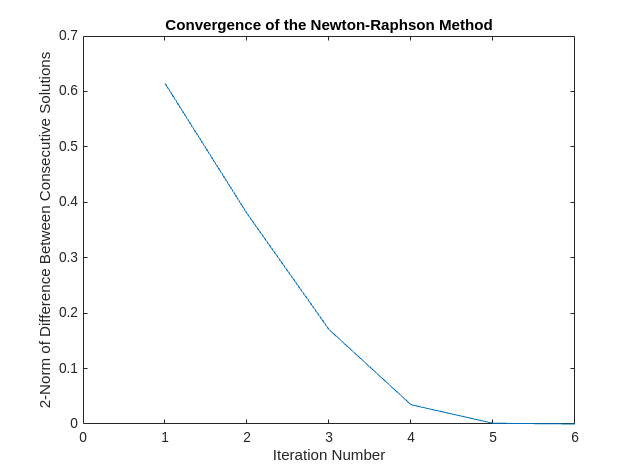

clear all;
func1 = @nlfunction;
c = 1
N = 200
time_BroydenIJ = zeros(N-10+1,1);
time_BroydenJ = zeros(N-10+1,1);

for I=10:N
Xguess = zeros(I,1);
brIJstart =tic ;
[XBrIJ,deltaXBroyden]  = NR_Broyden_InvJacobian(func1,Xguess,1e-6);
time_BroydenIJ(c) = toc(brIJstart) ;

brJstart =tic ;
[XBrJ,deltaXBroyden]  = NR_Broyden_Jacobian(func1,Xguess,1e-6);
time_BroydenJ(c) = toc(brJstart) ;

c =c+1;
end

figure()
clf
hold on 
plot(10:N,time_BroydenJ,'r-*')
plot(10:N,time_BroydenIJ,'b-*')

legend('Broyden approx. of $\textbf{J}$' ,'Broyden approx. of $\textbf{J}^{-1}$','Interpreter','latex')
title({'\textbf{Figure: Question 2f}','Time taken comparison for Broyden approx. methods'}, 'Interpreter', 'latex')
ylabel('Time [seconds]', 'Interpreter', 'latex')
xlabel('Number of equations', 'Interpreter', 'latex')
grid on 

*After running the cells  above, it can be seen that approximating the inverse of the Jacobian using Broyden's method (in blue) takes less time than it takes to approximate the Jacobian (in red). The reason is that approximating the inverse is faster than directly computing it.*

## **Exercise 4: Eigenvalues**

**The Power Iteration method is used to compute the dominant eigen value and the eigen vector associated with the dominant eigen value of a given matrix. Any random vector **$x_0$** can be written as the linear combination of **$n$** independent eigen vectors of a matrix **${\mathit{\mathbf{A}}}_{n\times n}$**: **


$${\mathit{\mathbf{x}}}_{0\;} =c_{1\;} {\mathit{\mathbf{v}}}_{1\;} +c_2 {\mathit{\mathbf{v}}}_2 +\cdots +c_n {\mathit{\mathbf{v}}}_{\mathit{\mathbf{n}}\;} \;\;\;$$
                                             
$$\left(1\right)$$


**On multiplying the above with matrix **$\mathit{\mathbf{A}}$** we get,**


$${\mathit{\mathbf{A}}\;\mathit{\mathbf{x}}}_{0\;} =c_{1\;} \mathit{\mathbf{A}}{\mathit{\mathbf{v}}}_{1\;} +c_2 {\;\mathit{\mathbf{A}}\;\mathit{\mathbf{v}}}_2 +\cdots +c_{n\;} \mathit{\mathbf{A}}{\mathit{\mathbf{v}}}_{\mathit{\mathbf{n}}\;}$$
                                  
$$\left(2\right)$$


**The vectors **${\mathit{\mathbf{v}}}_i$**'s are the eigen vectors of matrix **$\mathit{\mathbf{A}}$**, giving **$\mathit{\mathbf{A}}\;{\mathit{\mathbf{v}}}_{\mathit{\mathbf{i}}} =\lambda_{i\;} {\mathit{\mathbf{v}}}_{\mathit{\mathbf{i}}}$**. The symbol **$\lambda_{i\;}$**denotes the eigen value corresponding to eigen vector **${\mathit{\mathbf{v}}}_{\mathit{\mathbf{i}}}$**.**


$${\mathit{\mathbf{A}}\;\mathit{\mathbf{x}}}_{0\;} =c_{1\;} \lambda_{1\;} {\mathit{\mathbf{v}}}_{1\;} +c_2 {\;\lambda_{2\;} \;\mathit{\mathbf{v}}}_2 +\cdots +c_{n\;} \lambda_{n\;} {\mathit{\mathbf{v}}}_{\mathit{\mathbf{n}}\;\;}$$
                                
$$\left(3\right)$$


**Equation (3), can therefore be generalised: **


$${{\mathit{\mathbf{A}}}^{k\;} \;\mathit{\mathbf{x}}}_{0\;} =c_{1\;} \lambda_{1\;}^{k\;} {\mathit{\mathbf{v}}}_{1\;} +c_2 {\;\lambda_{2\;}^k \;\mathit{\mathbf{v}}}_2 +\cdots +c_{n\;} \lambda_{n\;}^{k\;} {\mathit{\mathbf{v}}}_{\mathit{\mathbf{n}}\;\;}$$
                              
$$\left(4\right)$$


**Without loss of generality, (4) can be written as the equation below:**


$${{\mathit{\mathbf{A}}}^{k\;} \;\mathit{\mathbf{x}}}_{0\;} =\lambda_{1\;}^{k\;} \left(c_{1\;} {\mathit{\mathbf{v}}}_{1\;} +c_2 {\;\frac{\lambda_{2\;}^k }{\lambda_{1\;}^{k\;} }\;\mathit{\mathbf{v}}}_2 +\cdots +c_{n\;} \frac{\lambda_{n\;}^{k\;} }{\lambda_{1\;}^{k\;} }{\mathit{\mathbf{v}}}_{\mathit{\mathbf{n}}\;\;} \right)$$
                     
$$\left(5\right)$$


**Assuming that **$\left|\lambda {\;}_1 \right|>$$\left|\lambda_2 \right|>\cdots \left|\lambda_n \right|$**, as **$k\to \infty$**, the terms with  **$\frac{\lambda_{j\;}^k }{\lambda_{1\;}^{k\;} }\to 0$**. Thus, as **$k\to \infty$**,  **${{\mathit{\mathbf{A}}}^{k\;} \;\mathit{\mathbf{x}}}_{0\;}$**converges to the eigen vector **${\mathit{\mathbf{v}}}_{1\;}$**corresponding to the largest eigen value. Write an iterative algorithm which computes the eigen vector and eigen value using the following recurssive formula,**


$${\mathit{\mathbf{v}}}^{\left(k+1\right)} =\;\frac{\mathit{\mathbf{A}}\;{\mathit{\mathbf{v}}}^{\left(k\right)} }{\parallel \mathit{\mathbf{A}}\;{\mathit{\mathbf{v}}}^{\left(k\right)} \parallel }$$
                                                                   
$$\left(6\right)$$
   

**where **${\mathit{\mathbf{v}}}^{\left(k+1\right)}$** is the eigen vector at **${\left(k+1\right)}^{\textrm{th}}$**iteration.**

**Stop the algorithm using when the **$\parallel {\mathit{\mathbf{v}}}^{\left(k+1\right)} \;-{\mathit{\mathbf{v}}}^{\left(k\right)} \parallel \;<\epsilon_{\textrm{tol}}$**, where **$\epsilon_{\textrm{tol}}$** is the input tolerance value. **

**The MATLAB function *****power_method(A,tol)***** written in the appendix uses the power iteration algorithm to compute the dominant eigen value and eigenvector. **

**The cell below is used to test the the *****power_method***** function. MATLAB's built in function, *****eig***** is used to compare results.**

M = randi(15,5) / 10;
A = M'*M; 

f =     58
    16
    48


[actual_e,actual_v] = power_method(A,1e-4)
[expected_v,expected_e] = eig(A) % verification
tolerance = 1e-4; 

J =     36     6     8
     4    12    -1
     1     2    12


difference = abs(max(max(expected_e)) - actual_e)

**Sources used to complete this section:**

- [https://www.mathworks.com/help/matlab/ref/eig.html](https://www.mathworks.com/help/matlab/ref/eig.html)

- [https://www.youtube.com/watch?v=nKd0lu3yThg](https://www.youtube.com/watch?v=nKd0lu3yThg)

- https://www.youtube.com/watch?v=AMDjmiQpk20&ab_channel=ATTIQIQBAL

# Appendix

### Exercise 2 Part a)

function [c, iterations] = bisectionMethod(f, a, b, tol)
    % inputs:
    % f is the function
    % a and b specify the interval

X =     0.4559
    1.0212
    0.2936


deltaX =     4.0254    0.7856    0.2826    0.0688    0.0051    0.0000    0.0000


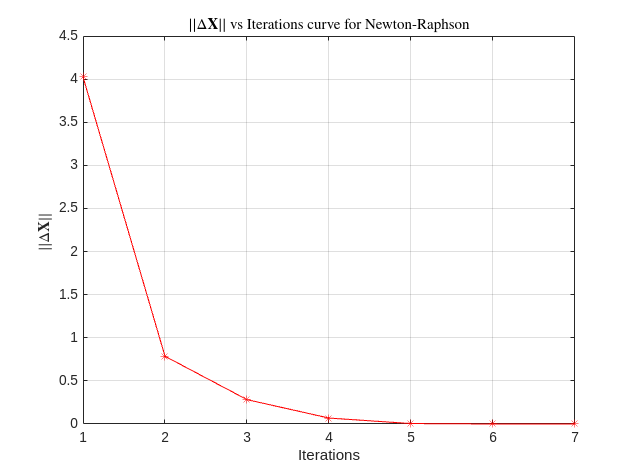

    % tol is the desired tolerance 
    
    % outputs:
    % c is the solution of the nonlinear equation
    % iterations is the number of iterations your method took to converge


    if f(a) * f(b) >= 0
        error('f(a) and f(b) do not have opposite signs')
    end
    
    iterations = 0;
    c = (a + b) / 2;

    while abs(b - a) / 2 > tol
        iterations = iterations + 1;
        fc = f(c); % compute the function value at the midpoint
        
        % Check if the root is found to within the specified tolerance

Xout =    -0.4110
   -1.0892
    0.5417


deltaXBroyden = 1.0e+03 *

    0.0770    0.1016    0.1840    0.2089    0.3844    0.4063    0.0632    0.0247    0.0765    0.0981    0.0121    0.0153    0.0071    0.0049    0.0029    0.0018    0.0011    0.0007    0.0005    0.0004    0.0007    0.0084    0.0094    0.0005    0.0008    0.0056    0.0090    0.0044    0.0057    0.0040    0.0020    0.0011    0.0041    0.0013    0.0017    2.1904    2.1903    0.0158    0.0163    0.0001    0.0004    0.0002    0.0001    0.0000    0.0000    0.0000    0.0005    0.0002    0.0004    0.0001


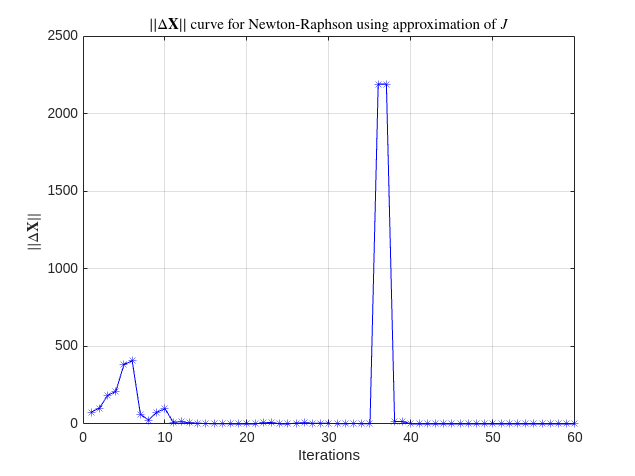

        if abs(fc) <= tol
            break;
        end
        
        % Update the endpoints and recalculate the midpoint
        if f(a) * fc < 0

            b = c;
        else
            a = c;
        end
        c = (a + b) / 2;
        
    end
end


Xout =    -0.4110
   -1.0892
    0.5417


deltaXBroyden = 1.0e+03 *

    0.0770    0.1016    0.1840    0.2089    0.3844    0.4063    0.0632    0.0247    0.0765    0.0981    0.0121    0.0153    0.0071    0.0049    0.0029    0.0018    0.0011    0.0007    0.0005    0.0004    0.0007    0.0084    0.0094    0.0005    0.0008    0.0056    0.0090    0.0044    0.0057    0.0040    0.0020    0.0011    0.0041    0.0013    0.0017    2.1904    2.1903    0.0158    0.0163    0.0001    0.0004    0.0002    0.0001    0.0000    0.0000    0.0000    0.0005    0.0002    0.0004    0.0001


### Exercise 2 Part b)

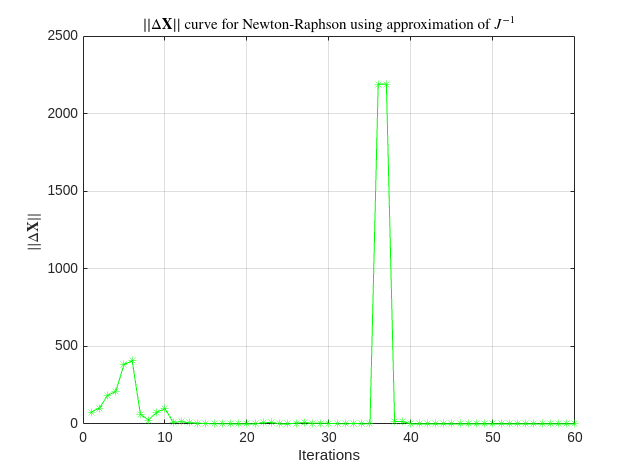

function [x, normdeltaX] = newtonraphson(f, fderiv, x0, tol, itermax)
    % Inputs:
    % f is the function 
    % fderiv is the derivative of nonlinear function 
    % x0 is the initial guess
    % tol is the desired tolerance 

    % itermax is the maximum number of iterations
    
    % Outputs:
    % x is the solution of the nonlinear equation
    % normdeltaX is the norm of deltaX at each iteration

    % Initialize the array to store the 2-Norm of deltaX
    normdeltaX = zeros(itermax, 1);

    for k = 1:itermax
        % Evaluate function and its derivative
        fx = f(x0);
        fderivx = fderiv(x0);

c = 1

N = 200

        if fderivx == 0
            error('Zero derivative. No solution found.');
        end
        
        x1 = x0 - fx / fderivx;
        normdeltaX(k) = norm(x1 - x0); % 2-Norm of deltaX
        
        % Check for convergence
        if abs(f(x1)) < tol || normdeltaX(k) < tol
            x = x1;
            % Truncate the normdeltaX array to the number of iterations done
            normdeltaX = normdeltaX(1:k);
            return;
        end
        
        % Update the guess for the next iteration
        x0 = x1;
    end
    
    error('Newton-Raphson failed to converge.');
end


### Exercise 3

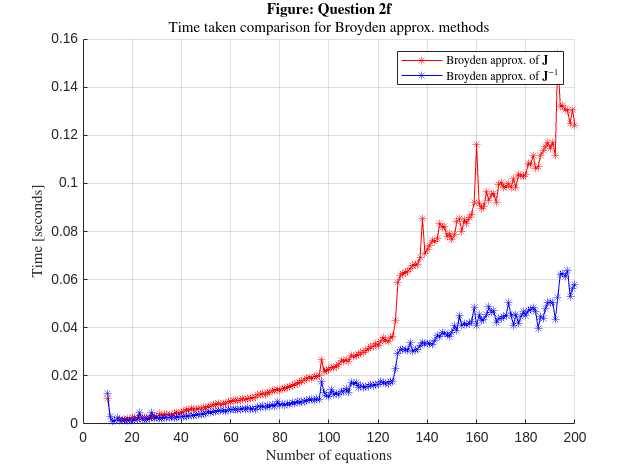

function [F] = nlfunction(x)
    % x is a colmns vecotr.

    n = length(x);

    F = zeros(n,1);
    i = 2:(n-1);
    F(i) = (3-2*x(i)).*x(i)-x(i-1)-2*x(i+1) + 1;
    F(n) = (3-2*x(n)).*x(n)-x(n-1) + 1;
    F(1) = (3-2*x(1)).*x(1)-2*x(2) + 1;
end

### Exercise 3 Part a)

function f  = evaluateEquations(x)
    f = zeros(3,1);


actual_e = 19.6455

actual_v =     0.5143
    0.3461
    0.5123
    0.3152
    0.5039


    f(1) = 9*x(1)^2+x(2)^2+x(3)^2-3;

expected_v =     0.6607   -0.4549    0.2568   -0.1614    0.5143
   -0.0357   -0.1504   -0.3230    0.8672    0.3461
   -0.2745    0.4999    0.6332    0.1068    0.5123
   -0.6948   -0.5834   -0.0494   -0.2740    0.3152
    0.0638    0.4244   -0.6530   -0.3681    0.5039


expected_e =     0.0081         0         0         0         0
         0    0.5822         0         0         0
         0         0    0.8592         0         0
         0         0         0    1.2549         0
         0         0         0         0   19.6455


    f(2) = x(1)^2+2*x(2)^2-x(3)-2;
    f(3) = x(1)+x(2)+12*x(3)-5;

difference = 6.6139e-08

end 

### Exercise 3 Part b)

function J  = evaluateJacobian(x)
    J = zeros(3,3);

    J(1,:) = [18*x(1), 2*x(2), 2*x(3)];
    J(2,:) = [2*x(1), 4*x(2), -1];
    J(3,:) = [1, 2, 12];
end

### Exercise 3 Part c)

function [Xout, normDeltaX] = NewtonRaphson(func, Jac, Xguess, tol)
    % Inputs:
    % func is the handle for evaluateEquations()
    % Jac i is the handle for evaluateJacobian()
    % Xguess is the initial guess vector
    % tol is the desired tolerance
    
    % Outputs:
    % Xout is the ouput vector
    % normDeltaX stores the norm of the deltaX at each iteration
    
    normDeltaX = [];
    Xk = Xguess;

    while 1
        deltaX = -Jac(Xk)\func(Xk);
        normDeltaX = [normDeltaX, norm(deltaX)];
        Xk = Xk + deltaX;
        normF = norm(func(Xk));

        if (normF < tol && norm(deltaX) < tol)
            break;
        end
    end

    Xout = Xk;
end

### Exercise 3 Part d)

function [Xout,normDeltaX]  = NR_Broyden_Jacobian(func, Xguess,tol)
    % Inputs:
    % func is the handle for evaluateEquations()
    % Xguess is a column vector, it is the initial guess vector
    % tol is the desired tolerance
    
    % Outputs:
    % Xout is the ouput vector
    % normDeltaX stores the norm of the deltaX at each iteration

    J = eye(length(Xguess));
    normDeltaX = [];
    Xk = Xguess;
    max_iteration = 1000;
    iteration = 0;

    while 1
        deltaX = -J\func(Xk);
        deltaF = func(Xk+deltaX)-func(Xk);
        normDeltaX = [normDeltaX, norm(deltaX)];
        Xk = Xk + deltaX;
        normF = norm(func(Xk));
                
        J = J + ((deltaF-J*deltaX)/(norm(deltaX)^2))*(deltaX).';

        if (normF < tol && norm(deltaX) < tol)
            break;
        end
        if iteration == max_iteration
            break;
        end
        iteration = iteration + 1;
    end

    Xout = Xk;
    
end


### Exercise 3 Part e)

function [Xout,normDeltaX]  = NR_Broyden_InvJacobian(func, Xguess,tol)
    % Inputs:
    % func is the handle for evaluateEquations()
    % Xguess is a column vector, it is the initial guess vector
    % tol is the desired tolerance
    
    % Outputs:
    % Xout is the ouput vector
    % normDeltaX stores the norm of the deltaX at each iteration

    J_inv = eye(length(Xguess));
    max_iteration = 1000;
    iteration = 0;
    normDeltaX = [];
    Xk = Xguess;

    while 1
        deltaX = -J_inv*func(Xk);
        deltaF = func(Xk+deltaX)-func(Xk);
        normDeltaX = [normDeltaX, norm(deltaX)];
        Xk = Xk + deltaX;
        normF = norm(func(Xk));

        J_inv = J_inv + ((deltaX-J_inv*deltaF)/(deltaX.'*J_inv*deltaF))*(deltaX.')*J_inv;

        if (normF < tol && norm(deltaX) < tol)
            break;
        end
        if iteration == max_iteration
            break;
        end
        iteration = iteration + 1;
    end

    Xout = Xk;
end

### Exercise 4

function [eig_val, eig_vector] = power_method(A, tol)
    % Find the largest eigen value for the input matrix and the eigen vector
    % associated with it.
    % Inputs: 
    % A is the matrix 
    % tol is the tolerance
    %
    % Outputs:
    % eig_val is the largest eigen value
    % eig_vector is the eigen vector associated with the largest eigen value
   
    eig_vector = rand(size(A, 1), 1);
    eig_vector = eig_vector / norm(eig_vector);
    eig_val = 0;
    delta = inf;

    while delta > tol
        w = A * eig_vector;
        new_eig_val = norm(w); % update the eigenvalue
        new_eig_vector = w / new_eig_val; % normalize eig_vector
        delta = norm(new_eig_vector - eig_vector); % verifying convergence
        eig_vector = new_eig_vector;
        eig_val = new_eig_val;
    end
end

### Helper Functions

function M = VandermondeMatrix(x,n)
    % x is the vector of input data
    % n is the degree of the polynomial
    [rows, ~] = size(x);
    M = ones(rows, n+1);
    
    for p = 1:n
        M(:,p+1) = M(:,p).*x;
    end
end

function y = forward_sub(L,b)
    % y is the vector
    % L is the lower triangular matrix
    n = length(b);
    [~, numCol] = size(L);
    y = zeros(n, 1);

    for i = 1:numCol
        if L(i, i) == 0
            error('Division by zero');
        end
        y(i) = (b(i) - L(i, 1:i-1) * y(1:i-1)) / L(i, i);
    end
end 

function X = backward_sub(U,y)
    % X is the vector
    % U is the upper triangular matrix
    [numRow, numCol] = size(U);
    X = zeros(numRow, 1);
    y = y(1:numRow);

    for i = numCol:-1:1
        if U(i, i) == 0
            error('Division by zero');
        end
        X(i) = (y(i) - U(i, i+1:numRow) * X(i+1:numRow)) / U(i, i);
    end
end  